**Defining Initial Values**

k1 = 4.66;
k2 = 4.66;
m1 = 0.0917;
m2 = 0.0765;
x10 = 100;
x20 = 50;
x1_d0 = 0;
x2_d0 = 0;
T = 10;
N = [1000];

**Finding state matrix A**

A = [ 0 0 1 0; 0 0 0 1; -(k1+k2)/m1 k2/m1 0 0; k2/m2 -k2/m2 0 0];

**Solving for the Horizontal Displacements and Setting the Axis for Subplots**

figure

for i = 1:length(N)
    [x1, x2, x1_d_est, x2_d_est, t_est] = IEMsolver2(A, x10, x20, x1_d0, x2_d0, T, N(i));
    
    subplot(2, 1, 1);
    hold on 
    plot(t_est, x1_d_est);
    
    subplot(2, 1, 2);
    hold on 
    plot(t_est, x2_d_est);
end

**Graphing the Displacement with Time**

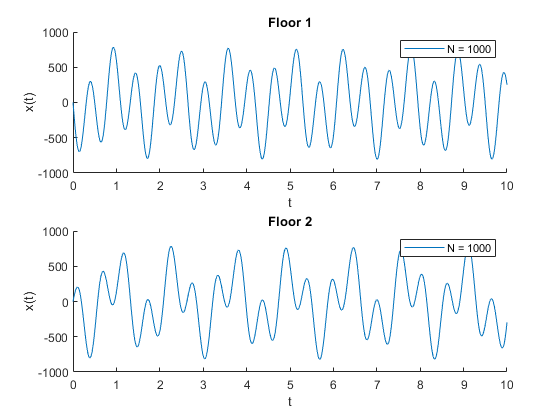

subplot(2, 1, 1)
title("Floor 1")
xlabel("t")
ylabel("x(t)")
legend("N = 1000")

subplot(2, 1, 2)
title("Floor 2")
xlabel("t")
ylabel("x(t)")
legend("N = 1000")

**Finding the Eigen Values for Matrix A**

eigen = eig(A)

eigen =    0.0000 +11.8542i
   0.0000 -11.8542i
  -0.0000 + 4.6935i
  -0.0000 - 4.6935i
